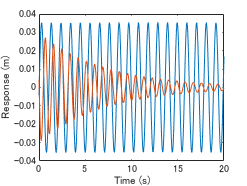

% ここ構造モデル

% 質量m [kg]
m = 2*10^6;

% guzai: 減衰定数 c/m = 2*GUZAI*W
guzai = 0.02;

% ばね定数k [N/m]
k = 5*10^6 / (10/200);

% 固有周期系角速度（rad/s）
w = (k/m)^0.5;

% 固有周期T [s]
T = 2*pi/w;



% ここ外力 p0 * sin(wp*t)

% 外力の振幅 [N]
p0 = 1*10^6;

% 外力の角速度 [rad/s]
wp = 6;

% 外力の周期 [s]
Tp = 2*pi/wp;


% ------------------------------------------------ %

% ここ応答計算

% 固有振動形角速度比 β
beta = wp/w;


% 振幅計算の一部 G0
G0 = (p0/k)/((1.0-beta^2)^2+(2*guzai*beta)^2);

% 振幅sin成分 定常応答
G1 = G0 * (1-beta^2);

% 振幅cos成分 定常応答
G2 = G0 * (-2*guzai*beta);

% 振幅sin成分 過渡応答
G3 = G0 * beta*(2*guzai^2-1+beta^2);

% 振幅cos成分 過渡応答
G4 = G0 * 2 * guzai * beta;

% ------------------------------------------------ %


% 時刻 t
t = 0:0.05:20;

% 外力プロット p
p = p0*sin(wp*t);

% plot(t,p)
% xlabel('Time (s)')
% ylabel('External Force (N)')

% print -dpng figure04


% 定常応答成分xs
xs = G1*sin(wp*t)+G2*cos(wp*t);

% 過渡応答成分xt
xt = (G3*sin(w*t) + G4*cos(w*t)).*exp(-guzai*w*t);

plot(t, xs, t, xt);
xlabel('Time (s)')
ylabel('Response (m)')

print -dpng ./06/figure06-1

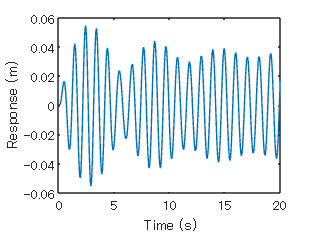


% 合成分プロット
x = xs+xt;

plot(t,x);
xlabel('Time (s)')
ylabel('Response (m)')

print -dpng ./06/figure06-2